# Lab 2

addpath('../LabFiles/Functions/')
addpath('../LabFiles/Images-m/')

## 1  Difference operators

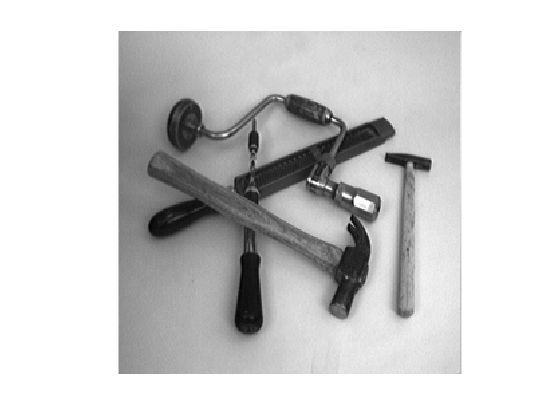

deltax = 0.5*[-1,0,1];
deltay = 0.5*[-1;0;1];

tools = few256;
showgrey(tools);

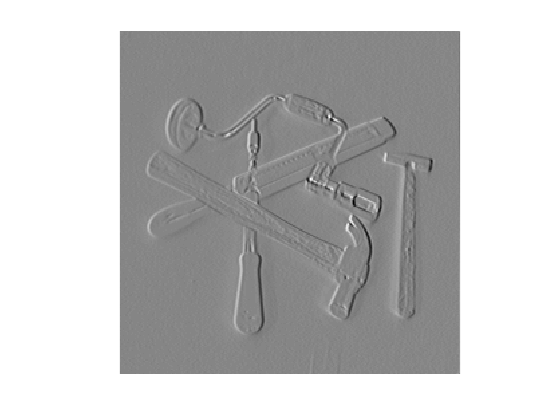

dxtools = conv2(tools, deltax, 'valid');
showgrey(dxtools);

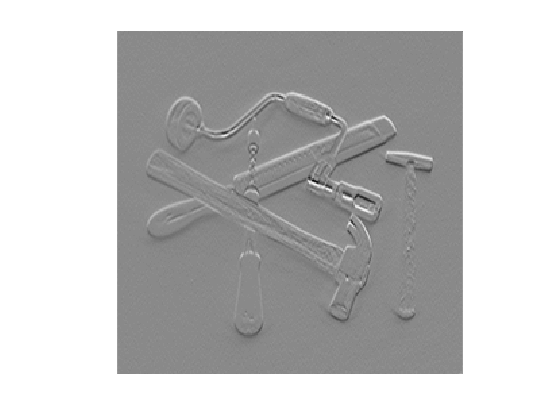

dytools = conv2(tools, deltay, 'valid');
showgrey(dytools)

## 2  Point–wise thresholding of gradient magnitudes

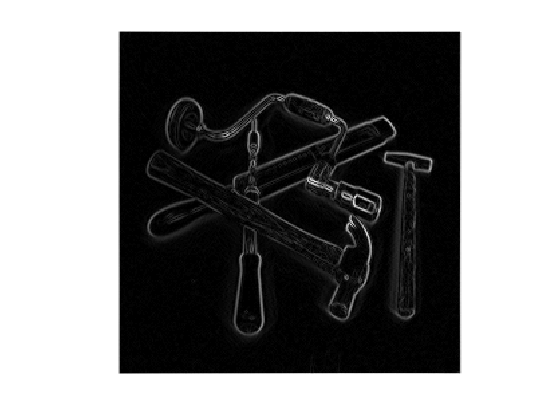

dxtools = conv2(tools, deltax, 'same');
dytools = conv2(tools, deltay, 'same');

gradmagntools = sqrt(dxtools .^2 + dytools .^2);
showgrey(gradmagntools)

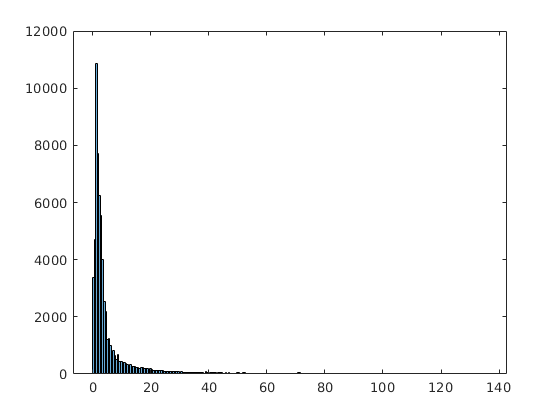

histogram(gradmagntools,256);

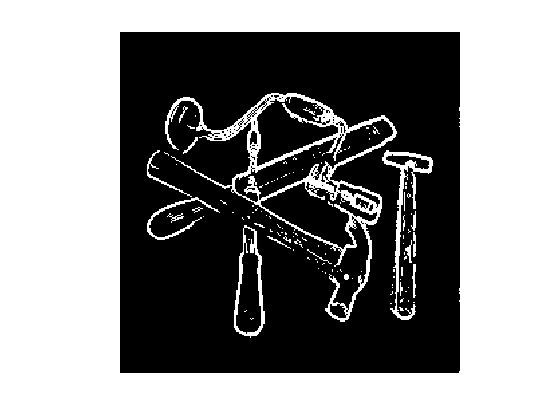

%set(gca, 'YScale', 'log')

showgrey((gradmagntools - 18) > 0)

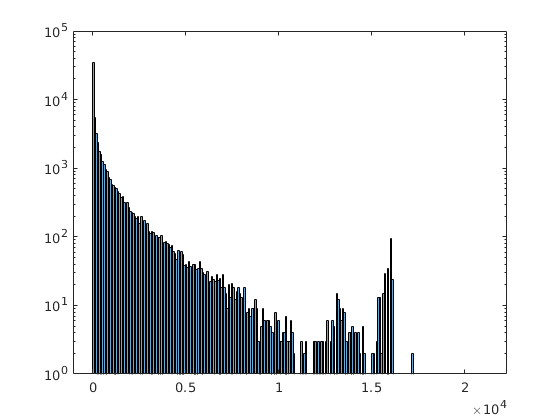

img = godthem256;
M = Lv(img);


histogram(M,256);
set(gca, 'YScale', 'log')

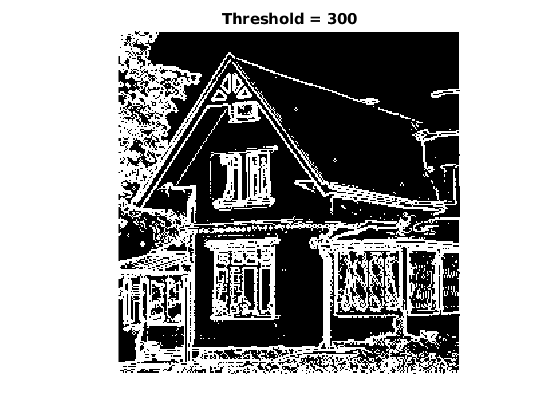

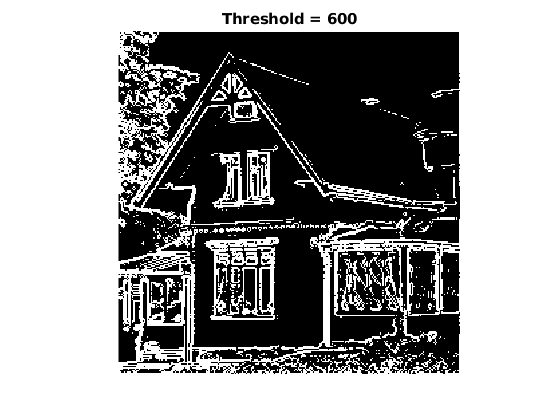

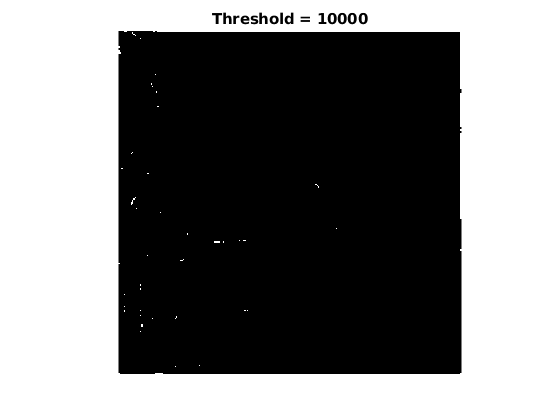


for threshold = [300,600,10000]
    figure();
    showgrey((Lv(img) - threshold) > 0)
    title(sprintf("Threshold = %g",threshold))
end

with smoothing

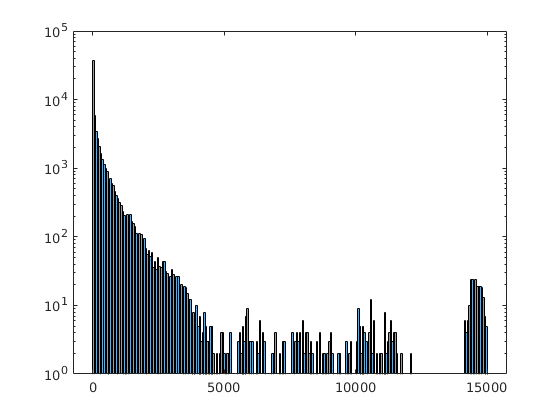

img = discgaussfft(godthem256,1);
M = Lv(img);


histogram(M,256);
set(gca, 'YScale', 'log')

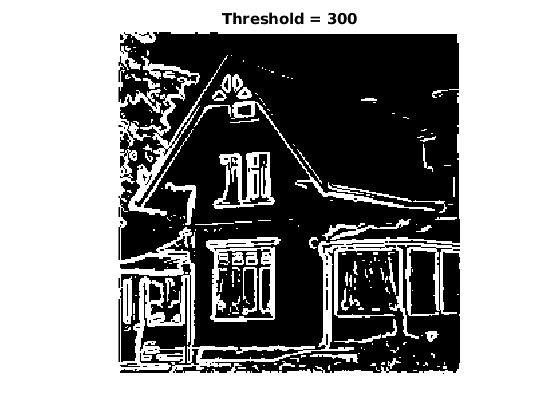

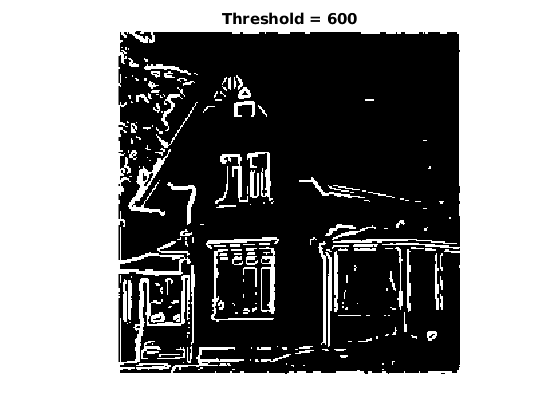

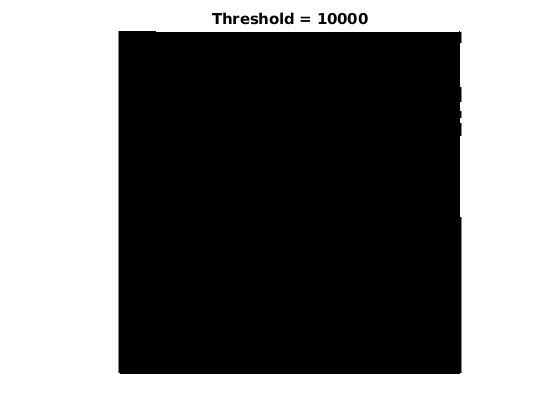


for threshold = [300,600,10000]
    figure();
    showgrey((Lv(img) - threshold) > 0)
    title(sprintf("Threshold = %g",threshold))
end

## 4  Computing differential geometry descriptors

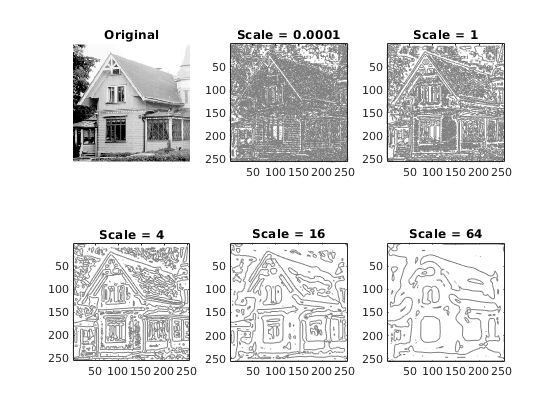

house = godthem256;
figure();

subplot(2,3,1);
showgrey(house);
title("Original")

idx = 2;
for scale = [0.0001 1.0 4.0 16.0 64.0]
    subplot(2,3,idx);
    contour(Lvvtilde(discgaussfft(house, scale )), [0 0]);
    title(sprintf("Scale = %g", scale));
    axis('image')
    axis('ij')
    idx = idx + 1;
end

saveas(gcf,'question4.svg')

Now let's see the third derivative

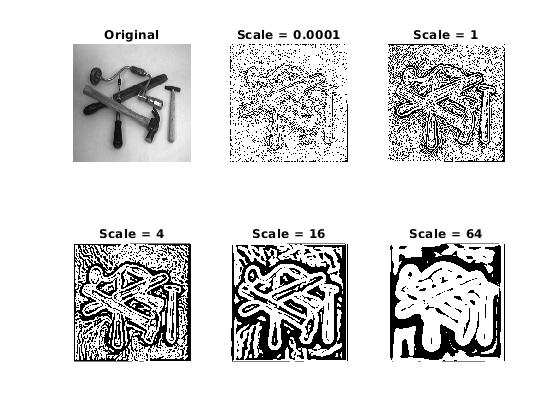

figure('DefaultAxesPosition', [0.1, 0.1, 0.8, 0.8]);
tools = few256;
subplot(2,3,1);
showgrey(tools);
title("Original");

idx = 2;
for scale = [0.0001 1.0 4.0 16.0 64.0]
    h = subplot(2,3,idx);
    showgrey(Lvvvtilde(discgaussfft(tools, scale)) < 0)
    title(sprintf("Scale = %g", scale));
    axis('image');
    axis('ij');
    idx = idx + 1;
end

saveas(gcf,'question5.svg')

## 5  Extraction of edge segments

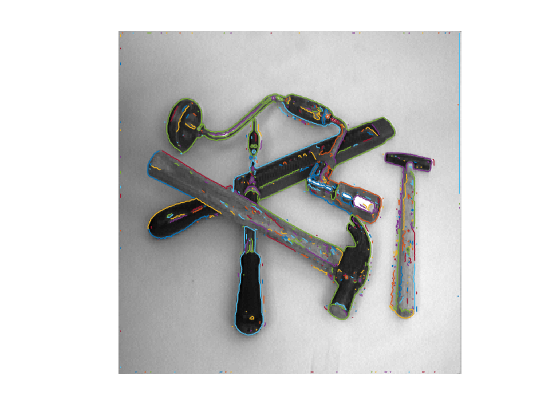

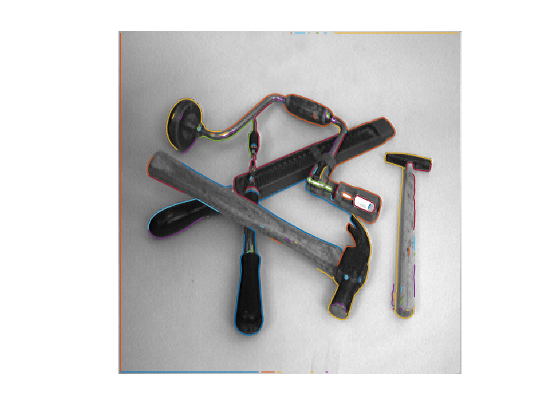

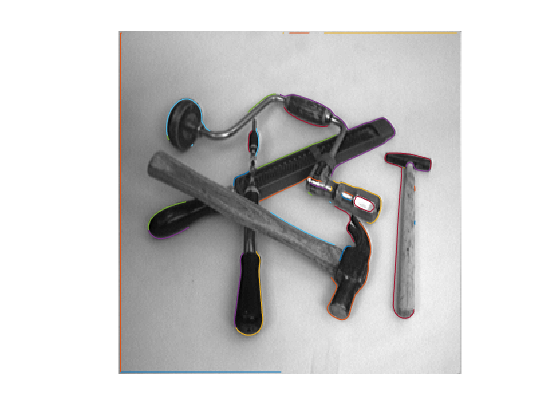

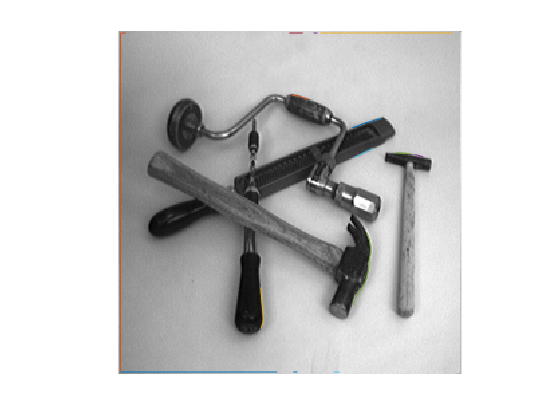

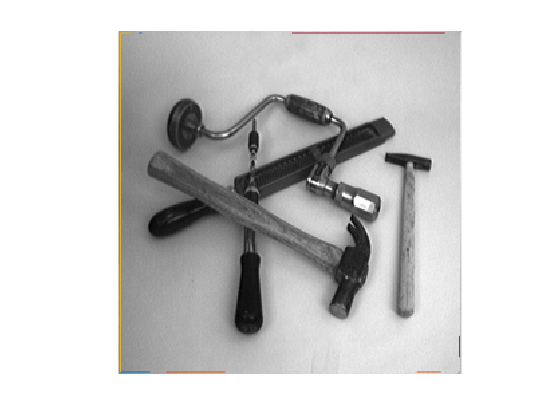

tools = few256;
warning ('off','all');
for scale = [0.0001 1.0 4.0 16.0 64.0]
    figure();
    curves = extractedge(tools,scale, 200, 'same');
    overlaycurves(tools, curves);

end

## 6  Hough transform

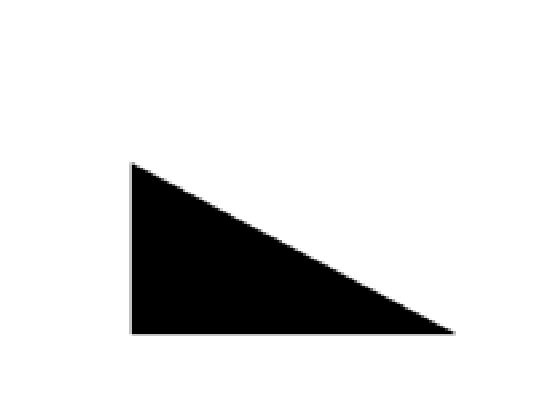

warning ('off','all');
testimage1 = triangle128;
F = [ ones(56, 128); zeros(16, 128); ones(56, 128)];
F = 1 - (1-F) .* (1-F');

smalltest1 = binsubsample(testimage1);

curves = extractedge(testimage1,scale, 200, 'same');
overlaycurves(testimage1, curves);

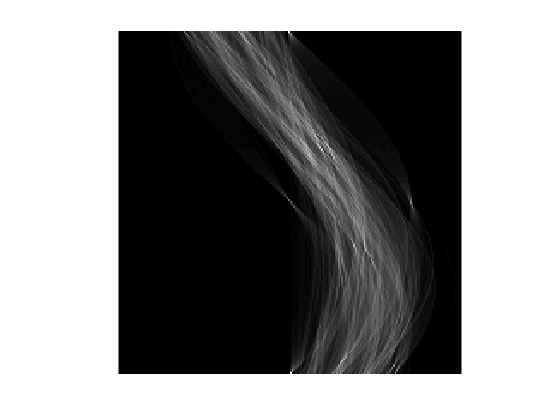

  252.0286

   718

Image size is 256

Output argument "linepar" (and maybe others) not assigned during call to "houghline".

Error in houghedgeline (line 16)
    [linepar, acc] = houghline(curves, magnitude, nrho, ntheta, gradmagnthreshold, nlines, verbose);


figure();


houghedgeline(tools,10,0,200,200,3,true);